addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')

supressed_print= evalc('run Nonlinear_Decoupled_EOMS_Try_2.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Derive the Partial Feedback Linearization Law for the Decoupled Nonlinear Dynamics and Run Simulation

## Partially Feedback Linearizing Torque Actuation

syms u_x

T_beta_FL_x = u_x/g_x(2) - f_x(2)/g_x(2)

$$T\_beta\_FL\_x = \frac{0.1429\,\left(5\,{\dot{\beta }}^{2}\,m_{b}\,x^{3}+5\,I_{p}^{\mathrm{xx}}\,{\dot{\beta }}^{2}\,x+5\,I_{p}^{\mathrm{xx}}\,g\,\sin\left(\beta \right)+7\,{\dot{\beta }}^{2}\,m_{b}\,{r_{b}}^{2}\,x+5\,{\dot{\beta }}^{2}\,m_{p}\,x\,{z_{p}}^{2}+5\,g\,m_{b}\,x^{2}\,\sin\left(\beta \right)+5\,g\,m_{p}\,{z_{p}}^{2}\,\sin\left(\beta \right)+14\,\dot{\beta }\,m_{b}\,r_{b}\,x\,\dot{x}-7\,g\,m_{b}\,r_{b}\,x\,\cos\left(\beta \right)-7\,g\,m_{p}\,r_{b}\,z_{p}\,\sin\left(\beta \right)\right)}{r_{b}}-\frac{u_{x}\,\left(m_{b}\,x^{2}+m_{p}\,{z_{p}}^{2}+I_{p}^{\mathrm{xx}}\right)}{r_{b}}$$

## Partially Feedback Linearized System

NL_Dcpld_FLd_EOMs_x = stateVec1_dot == expand(simplify(f_x + g_x*T_beta_FL_x))

$$NL\_Dcpld\_FLd\_EOMs\_x = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=u_{x}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=\frac{0.7143\,{\dot{\beta }}^{2}\,x}{r_{b}}-\frac{u_{x}}{r_{b}}+\frac{0.7143\,g\,\sin\left(\beta \right)}{r_{b}} \end{array}\right]$$

## Choose Virtual Input That Makes x Error States Decay to Zero

syms a b

First, define a characteristic polynomial in error dynamics. Utilize a pole placement approch to parameterize its behavior. 

char_poly_ex_eqn = e_x_ddot + a*e_x_dot + b*e_x == 0

$$char\_poly\_ex\_eqn = a\,e_{\dot{x}}+b\,e_{x}+e_{\ddot{x}}=0$$

Substitute the error states for absolute states and setpoint states. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, [e_x_ddot e_x_dot e_x ], [x_ddot_s - x_ddot, x_dot_s - x_dot , x_s - x])

$$char\_poly\_ex\_eqn = {\ddot{x}}_{s}-\ddot{x}-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)=0$$

xddot_from_char_poly = isolate(char_poly_ex_eqn, x_ddot)

$$xddot\_from\_char\_poly = \ddot{x}={\ddot{x}}_{s}-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)$$

roots_error_poly = poly([-5 -6]);
u_x_eqn = u_x == rhs(subs(xddot_from_char_poly ,[a b],roots_error_poly([2,3])))

$$u\_x\_eqn = u_{x}=-30\,x+30\,x_{s}+{\ddot{x}}_{s}-11\,\dot{x}+11\,{\dot{x}}_{s}$$


% u_x_fun = matlabFunction(rhs(associated_xddot));

### Setpoint Parameters

r_sim = 150; % radius of circular trajectory [mm]
omega_sim =  2*pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t);

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym;

### Find Derivatives of Trajectory

des_traj_sym_dot(t) = diff(des_traj_sym(t),t)

$$des\_traj\_sym\_dot(t) = 187.5000\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)-235.6194\,\cos\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

des_traj_sym_ddot(t) = diff(des_traj_sym_dot(t),t)

$$des\_traj\_sym\_ddot(t) = 589.0486\,{\mathrm{e}}^{-1.2500\,t}\,\cos\left(1.5708\,t\right)-234.3750\,{\mathrm{e}}^{-1.2500\,t}\,\sin\left(1.5708\,t\right)+370.1102\,\sin\left(1.5708\,t\right)\,\left({\mathrm{e}}^{-1.2500\,t}-1\right)$$

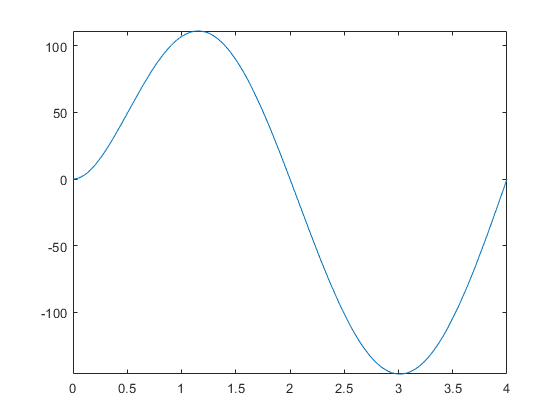

fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]);

des_traj_handle = matlabFunction([des_traj_sym(t);des_traj_sym_dot(t);des_traj_sym_ddot(t)]);

## Simulate the Controller and Find Out if the Unstable Pole is Actually an Issue

%Specify simulation time
% t_sim = 2*pi/omega_sim;
t_sim = 1;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

out = sim('Linear_Moving_Setpoint_Poly_Setting');